**Börsenkurs als 1D Brownische Bewegung**

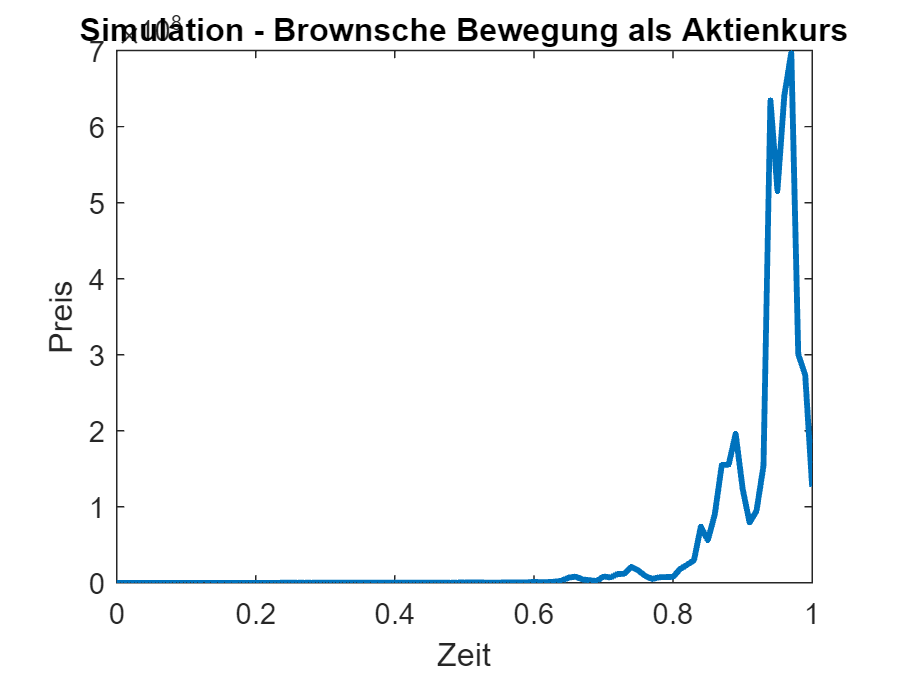

t = 1;
N = 100;
dt = t/N; 
sigma = 5; 
S0 = 1; %Anfangspreis


dB = sqrt(dt)*randn(1,N); %Weiner-Prozess
W = cumsum(dB); 
S = S0*exp((sigma^2/2)*dt*(1:N) + sigma*W);

plot(0:dt:t,[S0,S],'linewidth',2)
xlabel('Zeit')
ylabel('Preis')
title('Simulation - Brownsche Bewegung als Aktienkurs')

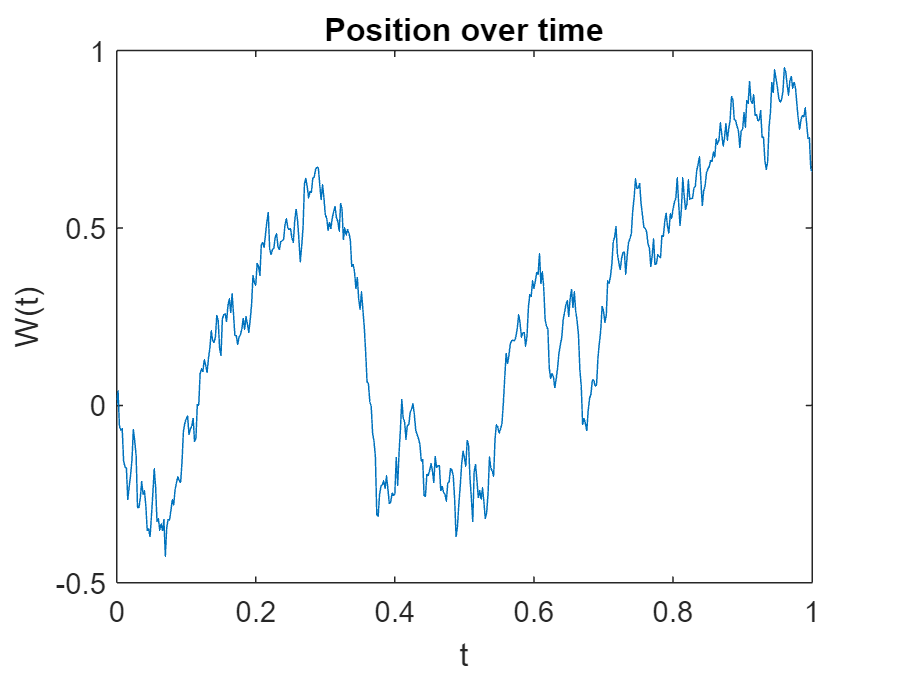

randn('state',100)
T = 1;
N = 500;
dt = T/N;
dW = sqrt(dt) * randn(1,N);
W = cumsum(dW);
plot(0:dt:T,[0,W])
xlabel('t')
ylabel('W(t)')
title('Position over time')

**2D Brownische Bewegung**

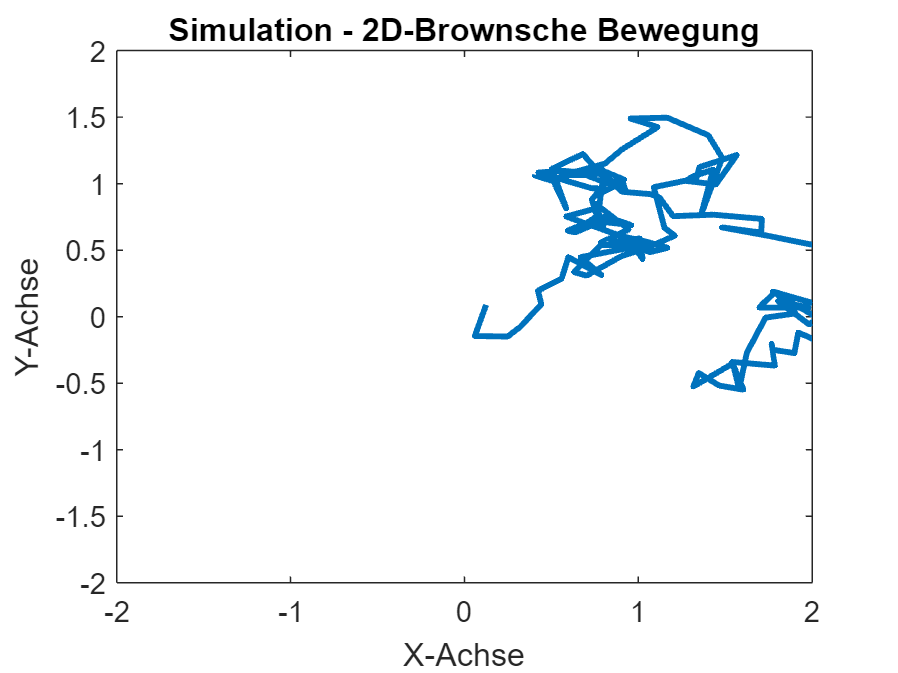

t = 1;
N = 200;
dt = t/N;
sigma = 2;
XY0 = [0,0];

dB = sqrt(dt)*randn(2,N);
W = cumsum(dB,2);
S = XY0' + sigma*W;

plot(S(1,:),S(2,:),'linewidth',2)
axis_max = 2;
xlim([-axis_max, axis_max]);
ylim([-axis_max, axis_max]);
xlabel('X-Achse')
ylabel('Y-Achse')
title('Simulation - 2D-Brownsche Bewegung')

Euler-Maruyama-Methode

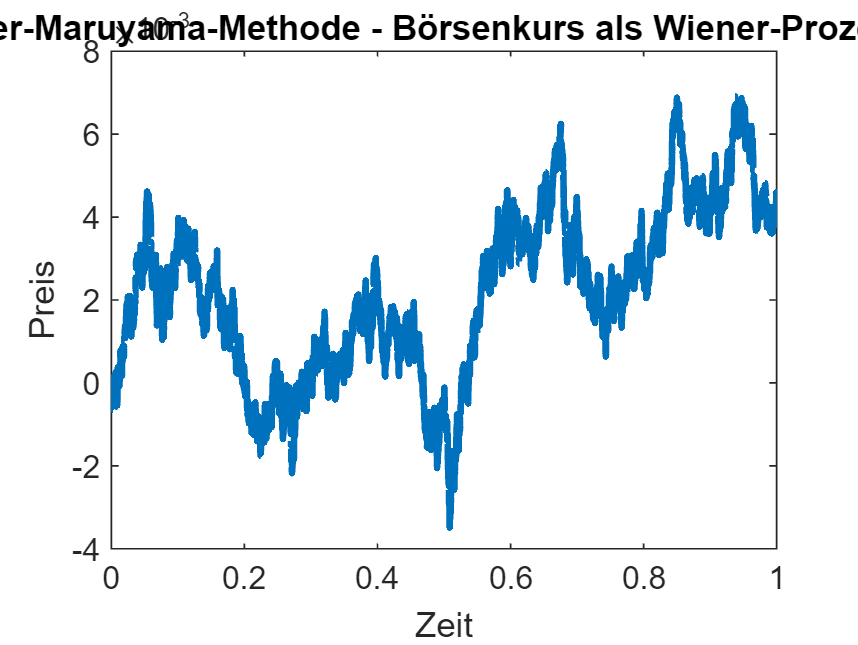

T = 1; 
N = 10000; 
dt = T/N; 
sigma = 1;
S0 = 0; 

dB = sqrt(dt)*randn(1,N);
S = zeros(1,N+1); 
S(1) = S0; 
for i = 1:N
    S(i+1) = S(i) + sigma*sqrt(dt)*dB(i);
end

plot(0:dt:T,S,'linewidth',2)
xlabel('Zeit')
ylabel('Preis')
title('Euler-Maruyama-Methode - Börsenkurs als Wiener-Prozesses')

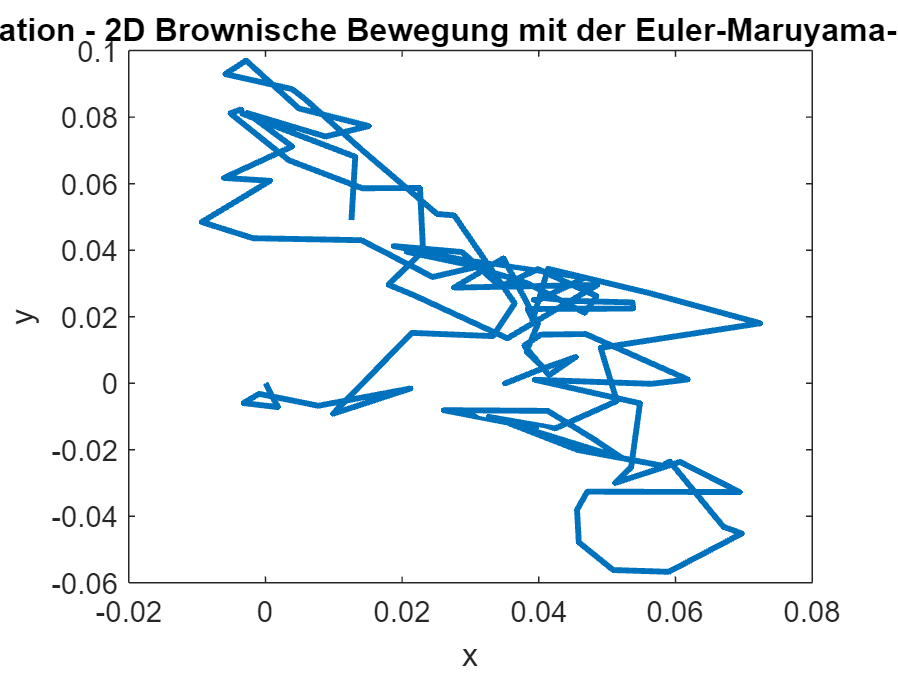

T = 1;
N = 100;
dt = T/N;
sigma = 1;
S0 = [0, 0];

dB = sqrt(dt)*randn(2, N);
S = zeros(2, N+1);
S(:,1) = S0';
for i = 1:N
    S(:,i+1) = S(:,i) + sigma*sqrt(dt)*dB(:,i);
end

plot(S(1,:),S(2,:),'linewidth',2)
xlabel('x')
ylabel('y')
title('Simulation - 2D Brownische Bewegung mit der Euler-Maruyama-Methode')